# Classify Time Series Using Transfer Learning and Scalograms

This example shows how to classify human electrocardiogram (ECG) signals using the continuous wavelet transform (CWT) and a deep convolutional neural network (CNN). We want to build a model that can classify the ECG signal while it is being acquired. We will split each training signal into chunks of 8 seconds, so we may have a classification every 8 seconds. 

Training a deep CNN from scratch is computationally expensive and requires a large amount of training data. In various applications, a sufficient amount of training data is not available, and synthesizing new realistic training examples is not feasible. In these cases, leveraging existing neural networks that have been trained on large data sets for conceptually similar tasks is desirable. This leveraging of existing neural networks is called transfer learning. 

In this example we adapt two deep CNNs, GoogLeNet and SqueezeNet, pretrained for image recognition to classify ECG waveforms based on a time-frequency representation.

## Data Description

In this example, you use ECG data obtained from three groups of people: persons with cardiac arrhythmia (ARR), persons with congestive heart failure (CHF), and persons with normal sinus rhythms (NSR). In total you use 162 ECG recordings from three PhysioNet databases: [MIT-BIH Arrhythmia Database](https://www.physionet.org/physiobank/database/mitdb/) [3][7], [MIT-BIH Normal Sinus Rhythm Database](https://www.physionet.org/physiobank/database/nsrdb/) [3], and [The BIDMC Congestive Heart Failure Database](https://www.physionet.org/physiobank/database/chfdb/) [1][3]. More specifically, 96 recordings from persons with arrhythmia, 30 recordings from persons with congestive heart failure, and 36 recordings from persons with normal sinus rhythms. The goal is to train a classifier to distinguish between ARR, CHF, and NSR.

## Download Data

The data used in this example are publicly available from [PhysioNet](https://physionet.org). The first step is to download the data from the GitHub® [repository](https://github.com/mathworks/physionet_ECG_data/). 

repoURL = 'https://github.com/mathworks/physionet_ECG_data/';
branch = 'main'; % Change to the correct branch if needed

% Construct the download URL
downloadURL = [repoURL, '/archive/refs/heads/', branch, '.zip'];

% Define the output file name
outputFileName = 'physionet_ECG_data-main.zip';

% Download the ZIP file
websave(outputFileName, downloadURL);

unzip(fullfile("physionet_ECG_data-main.zip"))

Unzipping creates the folder `physionet-ECG_data-main` in your temporary directory. This folder contains the text file `README.md` and `ECGData.zip`. The `ECGData.zip` file contains 

- `ECGData.mat`

- `Modified_physionet_data.txt`

- `License.txt`

`ECGData.mat` holds the data used in this example. The text file, `Modified_physionet_data.txt`, is required by PhysioNet's copying policy and provides the source attributions for the data as well as a description of the preprocessing steps applied to each ECG recording.

Unzip `ECGData.zip` in `physionet-ECG_data-main`. Load the data file into your MATLAB workspace.

unzip(fullfile("physionet_ECG_data-main","ECGData.zip"),fullfile("physionet_ECG_data-main"))
load(fullfile("physionet_ECG_data-main","ECGData.mat"))

Load the data into your workspace.

%make sure that the path is added
addpath("physionet_ECG_data-main")
load("ECGData.mat")
mkdir(fullfile("../data"));
save(fullfile("../data/ECGData.mat"),"ECGData"); % make a copy for later use

`ECGData` is a structure array with two fields: `Data` and `Labels`. `Data` is a 162-by-65536 matrix where each row is an ECG recording sampled at 128 hertz. Each ECG time series has a total duration of 512 seconds. `Labels` is a 162-by-1 cell array of diagnostic labels, one for each row of `Data`. The three diagnostic categories are: `'ARR'` (arrhythmia), `'CHF'` (congestive heart failure), and `'NSR'` (normal sinus rhythm).

To store the preprocessed data of each category, first create an ECG data directory `dataDir` inside `tempdir`. Then create three subdirectories in `'data'` named after each ECG category. The helper function `helperCreateECGDirectories` does this. `helperCreateECGDirectories` accepts `ECGData`, the name of an ECG data directory, and the name of a parent directory as input arguments. You can replace `tempdir` with another directory where you have write permission. You can find the source code for this helper function in the Supporting Functions section at the end of this example.

helperCreateECGDirectories(ECGData,fullfile("../data"))

Plot a representative of each ECG category. The helper function `helperPlotReps` does this. `helperPlotReps` accepts `ECGData` as input. You can find the source code for this helper function in the Supporting Functions section at the end of this example.

helperPlotReps(ECGData)

## Create Time-Frequency Representations

After making the folders, create time-frequency representations of the ECG signals. These representations are called scalograms. A scalogram is the absolute value of the CWT coefficients of a signal.

To create the scalograms, precompute a CWT filter bank. Precomputing the CWT filter bank is the preferred method when obtaining the CWT of many signals using the same parameters.

Before generating the scalograms, examine one of them. Create a CWT filter bank using [cwtfilterbank](docid:wavelet_ref#mw_b8b0ddad-1703-45db-a219-febab76b6d1f) for a signal with 1000 samples. Use the filter bank to take the CWT of the first 1000 samples of the signal and obtain the scalogram from the coefficients.

Fs = 128;
fb = cwtfilterbank(SignalLength=1000, ...
    SamplingFrequency=Fs, ...
    VoicesPerOctave=12);
sig = ECGData.Data(1,1:1000);
[cfs,frq] = wt(fb,sig);
t = (0:999)/Fs;
figure
pcolor(t,frq,abs(cfs))
set(gca,"yscale","log")
shading interp
axis tight
title("Scalogram")
xlabel("Time (s)")
ylabel("Frequency (Hz)")

Use the helper function `helperCreateRGBfromTF` to create the scalograms as RGB images and write them to the appropriate subdirectory in `dataDir`. The source code for this helper function is in the Supporting Functions section at the end of this example. To be compatible with the GoogLeNet architecture, each RGB image is an array of size 224-by-224-by-3.

Additionally, at this point we will split the ECG data into chunks of 8 seconds (1024 samples) as we want to classify individual chunks of the signal. The chunks are saved to ECGData.Data. We now have 20574 8-s-signals. To reduce the amount of data for training we will only create a scalogramm for every 16th chunk.

%rearrange the data into shorter chunks of the signal
ds=1024; %corresponds to 8 seconds
sz=size(ECGData.Data); %e.g. dataTrain after the split... have to change this...
stream_data=zeros(sz(1)*(65536/ds*2-1),ds);
i=1;
for m=1:sz(1)
    for n=1:ds/2:65536-ds/2
        data_window=ECGData.Data(m,n:n+ds-1);
        stream_data(i,:)=data_window;
        i=i+1;
    end
end

ECGData.Data=stream_data;
ECGData.Labels=reshape(repmat(ECGData.Labels,[1 127])',[20574 1]);

% select a subset of the data
ECGData.Data_small=ECGData.Data(1:16:end,:);
ECGData.Labels_small=ECGData.Labels(1:16:end);

% create scalograms
helperCreateRGBfromTF(ECGData,fullfile("../data"));

## Divide into Training and Validation Data

Load the scalogram images as an image datastore. The [imageDatastore](docid:matlab_ref#butueui-1) function automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore enables you to store large image data, including data that does not fit in memory, and efficiently read batches of images during training of a CNN.

allImages = imageDatastore(fullfile("../data"), ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");

Randomly divide the images into two groups, one for training and the other for validation. Use 80% of the images for training, and the remainder for validation.

[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,"randomized");
disp("Number of training images: "+num2str(numel(imgsTrain.Files)))
disp("Number of validation images: "+num2str(numel(imgsValidation.Files)))
%save this datastore for later use
save(fullfile("../data/datastores_CNN.mat"),"imgsTrain","imgsValidation");

## GoogLeNet

**Load**

Load the pretrained GoogLeNet neural network. If Deep Learning Toolbox™ Model *for GoogLeNet Network* support package is not installed, the software provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click **Install**.

net = imagePretrainedNetwork("googlenet");

Visualize and analyze the GoogLeNet network using the function `analyzeNetwork`.

analyzeNetwork(net)

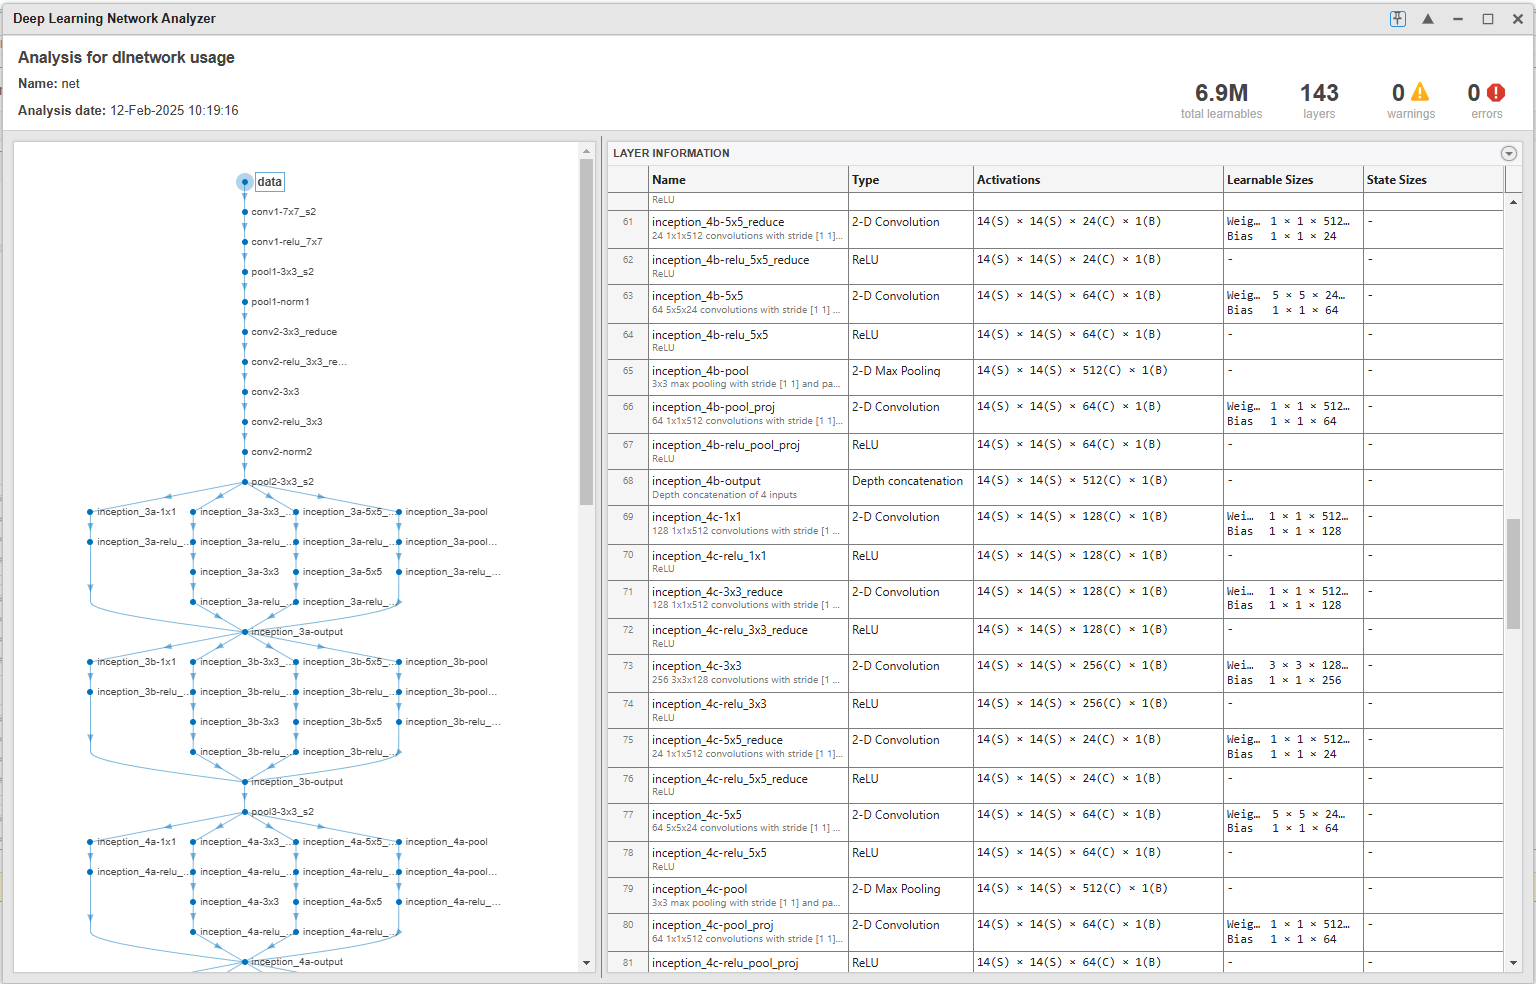

Inspect the first element of the network `Layers` property. Confirm that GoogLeNet requires RGB images of size 224-by-224-by-3.

net.Layers(1)

**Modify GoogLeNet Network Parameters**

Each layer in the network architecture can be considered a filter. The earlier layers identify more common features of images, such as blobs, edges, and colors. Subsequent layers focus on more specific features in order to differentiate categories. GoogLeNet is pretrained to classify images into 1000 object categories. You must retrain GoogLeNet for our ECG classification problem.

Inspect the last four layers of the network.

net.Layers(end-3:end)

To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability. See [dropoutLayer](docid:nnet_ref#mw_9d3adffa-df2e-40f8-9f15-972965a8d78d) for more information. The final dropout layer in the network, `pool5-drop_7x7_s1`, has a dropout probability of 0.4. Replace it with a dropout layer of probability 0.6.

newDropoutLayer = dropoutLayer(0.6,"Name","new_Dropout");
net = replaceLayer(net,"pool5-drop_7x7_s1",newDropoutLayer);

The convolutional layers of the network extract image features. Then the final learnable layer, `loss3-classifier`, in GoogLeNet, contains information on how to combine the features that the network extracts into class probabilities. The original GoogLeNet was trained on 1000 classes, so this layer has an output size of 1000. To retrain GoogLeNet to classify the RGB images into 3 classes, replace it with new layer adapted to the data.

Replace the fully connected layer `loss3-classifier` with a new fully connected layer with the number of neurons equal to the number of classes. To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer.

numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,"Name","new_fc", ...
    "WeightLearnRateFactor",5,"BiasLearnRateFactor",5);
net = replaceLayer(net,"loss3-classifier",newConnectedLayer);

Inspect the last five layers. Confirm you have replaced the dropout, convolutional, and fully connected layers.

net.Layers(end-3:end)

**Set Training Options and Train GoogLeNet**

Training a neural network is an iterative process that involves minimizing a loss function. To minimize the loss function, a gradient descent algorithm is used. In each iteration, the gradient of the loss function is evaluated and the descent algorithm weights are updated.

Training can be tuned by setting various options. `InitialLearnRate` specifies the initial step size in the direction of the negative gradient of the loss function. `MiniBatchSize` specifies how large of a subset of the training set to use in each iteration. One epoch is a full pass of the training algorithm over the entire training set. `MaxEpochs` specifies the maximum number of epochs to use for training. Choosing the right number of epochs is not a trivial task. Decreasing the number of epochs has the effect of underfitting the model, and increasing the number of epochs results in overfitting.

Use the [trainingOptions](docid:nnet_ref#bu59f0q) function to specify the training options. Visualize training progress by setting `Plots` to `training-progress`. Use the stochastic gradient descent with momentum optimizer. By default, training is done on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™. To see which GPUs are supported, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

batchsize = 147;
imgsTrain.ReadSize = batchsize; % 

options = trainingOptions("sgdm", ...
    MiniBatchSize=batchsize, ...
    MaxEpochs=30, ...
    InitialLearnRate=1e-3, ...
    Verbose=true, ...
    ValidationData=imgsValidation, ...
    ValidationFrequency=7, ...
    Plots="training-progress", ...
    Metrics="accuracy");


Train the network. It is recommended to run training on a GPU, on a desktop CPU it may take 5-20 minutes, depending on your machine. The command window displays training information during the run. Results include epoch number, iteration number, time elapsed, mini-batch accuracy, validation accuracy, and loss function value for the validation data.

doTraining=true;
if doTraining
    trainedGN = trainnet(imgsTrain,net,"crossentropy",options);
else
    load("trained_GN.mat")
end

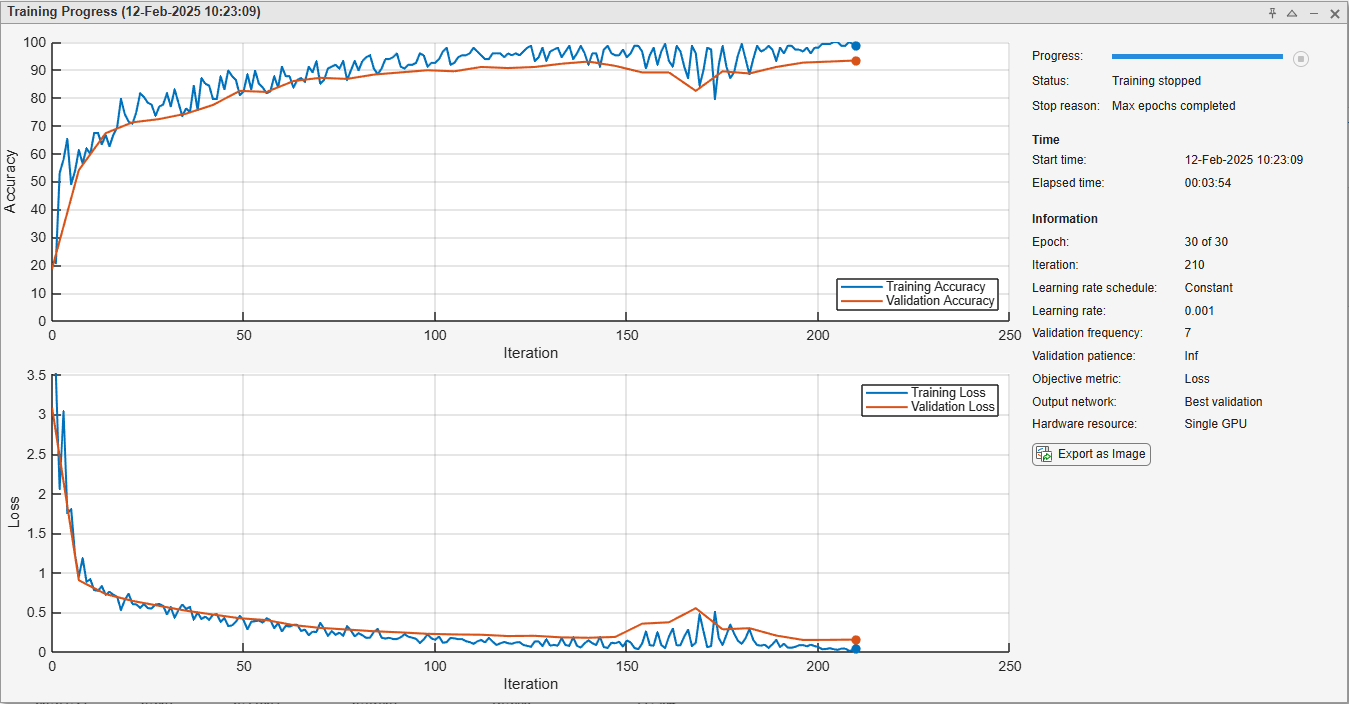

**Evaluate GoogLeNet Accuracy**

Evaluate the network using the validation data. Make predictions using the [`minibatchpredict`](docid:nnet_ref.mw_c7ae5ad7-5485-4270-8657-694ab264fb57) function and convert the scores to labels using the [`scores2label`](docid:nnet_ref.mw_b4669b80-206b-472f-a9eb-7e9642b3c38c) function. By default, the `minibatchpredict` function uses a GPU if one is available. 

classNames = categories(imgsTrain.Labels);
scores = minibatchpredict(trainedGN,imgsValidation);
YPred = scores2label(scores,classNames);
accuracy = mean(YPred==imgsValidation.Labels);
disp("GoogLeNet Accuracy: "+num2str(100*accuracy)+"%")

Display the classification results in a confusion chart. 

figure
confusionchart(imgsValidation.Labels,YPred)

The accuracy is identical to the validation accuracy reported on the training visualization figure. The scalograms were split into training and validation collections. Both collections were used to train GoogLeNet. The ideal way to evaluate the result of the training is to have the network classify data it has not seen. Since there is an insufficient amount of data to divide into training, validation, and testing, we treat the computed validation accuracy as the network accuracy.

**Explore GoogLeNet Activations**

Each layer of a CNN produces a response, or activation, to an input image. However, there are only a few layers within a CNN that are suitable for image feature extraction. Inspect the first five layers of the trained network.

trainedGN.Layers(1:5)

The layers at the beginning of the network capture basic image features, such as edges and blobs. To see this, visualize the network filter weights from the first convolutional layer. There are 64 individual sets of weights in the first layer.

wghts = trainedGN.Layers(2).Weights;
wghts = rescale(wghts);
wghts = imresize(wghts,8);
I = imtile(wghts,GridSize=[8 8]);
figure
imshow(I)
title("First Convolutional Layer Weights")

You can examine the activations and discover which features GoogLeNet learns by comparing areas of activation with the original image. For more information, see [Visualize Activations of a Convolutional Neural Network](docid:nnet_ug#bvl0ibp) and [Visualize Features of a Convolutional Neural Network](docid:nnet_ug#bvm8dx7).

Examine which areas in the convolutional layers activate on an image from the `ARR` class. Compare with the corresponding areas in the original image. Each layer of a convolutional neural network consists of many 2-D arrays called *channels*. Pass the image through the network and examine the output activations of the first convolutional layer,  `conv1-7x7_s2`.

convLayer = "conv1-7x7_s2";

imgClass = "ARR";
imgName = "ARR_10.jpg";
imarr = imread(fullfile(parentDir,dataDir,imgClass,imgName));

trainingFeaturesARR = predict(trainedGN,single(imarr),Outputs=convLayer);
sz = size(trainingFeaturesARR);
trainingFeaturesARR = reshape(trainingFeaturesARR,[sz(1) sz(2) 1 sz(3)]);
figure
I = imtile(rescale(trainingFeaturesARR),GridSize=[8 8]);
imshow(I)
title(imgClass+" Activations")

Find the strongest channel for this image. Compare the strongest channel with the original image.

imgSize = size(imarr);
imgSize = imgSize(1:2);
[~,maxValueIndex] = max(max(max(trainingFeaturesARR)));
arrMax = trainingFeaturesARR(:,:,:,maxValueIndex);
arrMax = rescale(arrMax);
arrMax = imresize(arrMax,imgSize);
figure
I = imtile({imarr,arrMax});
imshow(I)
title("Strongest "+imgClass+" Channel: "+num2str(maxValueIndex))

## SqueezeNet

SqueezeNet is a deep CNN whose architecture supports images of size 227-by-227-by-3. Even though the image dimensions are different for GoogLeNet, you do not have to generate new RGB images at the SqueezeNet dimensions. You can use the original RGB images.

**Load**

Load the pretrained SqueezeNet neural network. If Deep Learning Toolbox™ Model *for SqueezeNet Network* support package is not installed, the software provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click **Install**.

netsqz = imagePretrainedNetwork("squeezenet");

Extract the layer graph from the network. Confirm SqueezeNet has fewer layers than GoogLeNet. Also confirm that SqueezeNet is configured for images of size 227-by-227-by-3.

disp("Number of Layers: "+num2str(numel(netsqz.Layers)))
netsqz.Layers(1)

**Modify SqueezeNet Network Parameters**

To retrain SqueezeNet to classify new images, make changes similar to those made for GoogLeNet.

Inspect the last five network layers.

netsqz.Layers(end-5:end)

Replace the last dropout layer in the network with a dropout layer of probability 0.6.

tmpLayer = netsqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,"Name","new_dropout");
netsqz = replaceLayer(netsqz,tmpLayer.Name,newDropoutLayer);

Unlike GoogLeNet, the last learnable layer in SqueezeNet is a 1-by-1 convolutional layer, `conv10`, and not a fully connected layer. Replace the layer with a new convolutional layer with the number of filters equal to the number of classes. As was done with GoogLeNet, increase the learning rate factors of the new layer.

numClasses = numel(categories(imgsTrain.Labels));
tmpLayer = netsqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        "Name","new_conv", ...
        "WeightLearnRateFactor",10, ...
        "BiasLearnRateFactor",10);
netsqz = replaceLayer(netsqz,tmpLayer.Name,newLearnableLayer);

Inspect the last five layers of the network. Confirm the dropout and convolutional layers have been changed.

netsqz.Layers(end-5:end)

**Prepare RGB Data for SqueezeNet**

The RGB images have dimensions appropriate for the GoogLeNet architecture. Create augmented image datastores that automatically resize the existing RGB images for the SqueezeNet architecture. For more information, see [augmentedImageDatastore](docid:nnet_ref#mw_fd462475-1bc2-4f76-968c-c75721e5195f).

augimgsTrain = augmentedImageDatastore([227 227],imgsTrain);
augimgsValidation = augmentedImageDatastore([227 227],imgsValidation);

**Set Training Options and Train SqueezeNet**

Create a new set of training options to use with SqueezeNet, and train the network.

ilr = 1e-3;
miniBatchSize = 147;
maxEpochs = 30;
valFreq = floor(numel(augimgsTrain.Files)/miniBatchSize);
opts = trainingOptions("sgdm", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=maxEpochs, ...
    InitialLearnRate=ilr, ...
    ValidationData=augimgsValidation, ...
    ValidationFrequency=valFreq, ...
    Verbose=1, ...
    Plots="training-progress", ...
    Metrics="accuracy");

if doTraining
    trainedSN = trainnet(augimgsTrain,netsqz,"crossentropy",opts);
else
    load("trained_SN.mat")
end

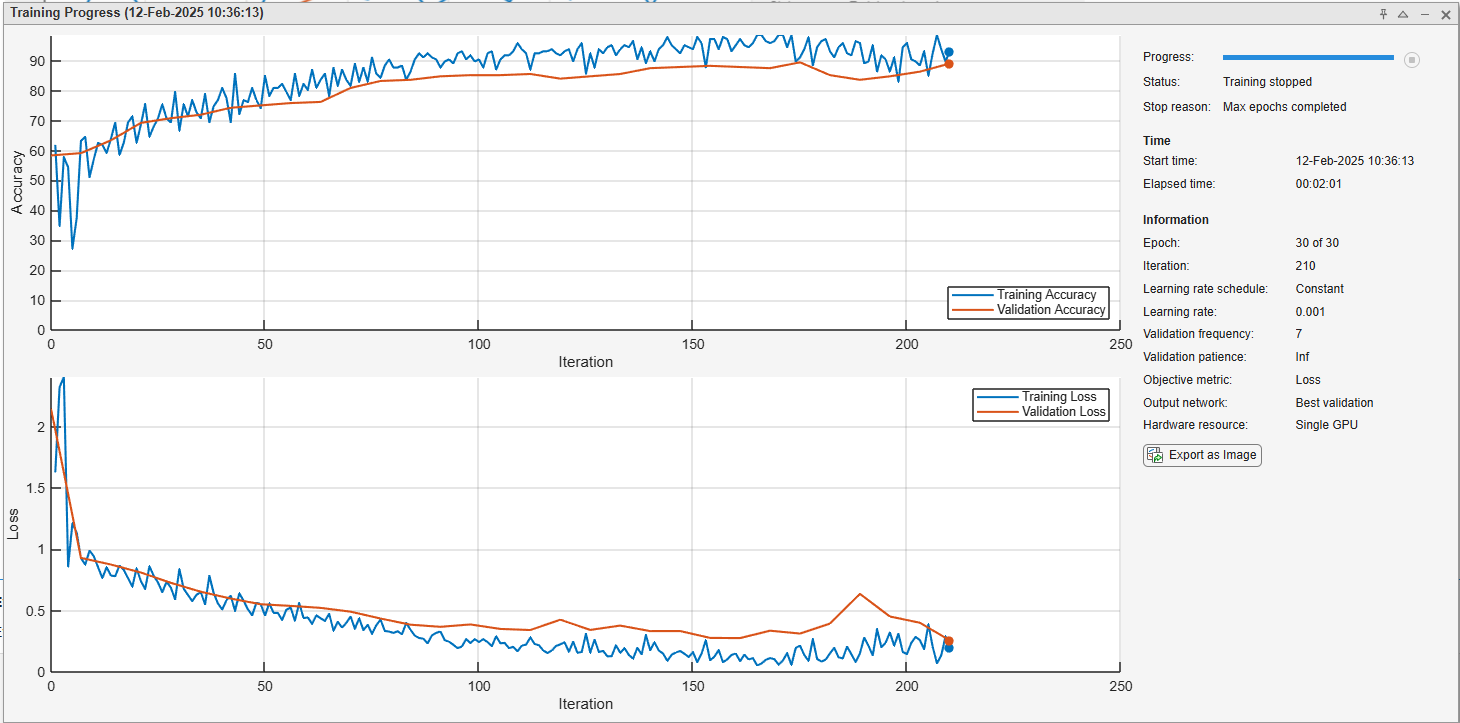

**Evaluate SqueezeNet Accuracy**

Evaluate the network using the validation data.

scores = minibatchpredict(trainedSN,augimgsValidation);
YPred = scores2label(scores,classNames);
accuracy = mean(YPred==imgsValidation.Labels);
disp("SqueezeNet Accuracy: "+num2str(100*accuracy)+"%")

Display the classification results in a confusion chart. 

figure
confusionchart(imgsValidation.Labels,YPred)

## Conclusion

This example shows how to use transfer learning and continuous wavelet analysis to classify three classes of ECG signals by leveraging the pretrained CNNs GoogLeNet and SqueezeNet. Wavelet-based time-frequency representations of ECG signals are used to create scalograms. RGB images of the scalograms are generated. The images are used to fine-tune both deep CNNs. Activations of different network layers were also explored.

This example illustrates one possible workflow you can use for classifying signals using pretrained CNN models. Other workflows are possible. [Deploy and Run Signal Classification on NVIDIA Jetson Using Wavelet Analysis and Deep Learning](docid:wavelet_ug#mw_3aaccec1-e108-40de-8aa4-cd1757c916eb) and [Signal Classification Code Generation Using Wavelets and Deep Learning on Raspberry Pi](docid:wavelet_ug#mw_dfd7fb96-374c-41be-8d0a-da0d0f29458e) show how to deploy code onto hardware for signal classification. GoogLeNet and SqueezeNet are models pretrained on a subset of the ImageNet database [10], which is used in the ImageNet Large-Scale Visual Recognition Challenge (ILSVRC) [8]. The ImageNet collection contains images of real-world objects such as fish, birds, appliances, and fungi. Scalograms fall outside the class of real-world objects. In order to fit into the GoogLeNet and SqueezeNet architecture, the scalograms also underwent data reduction. Instead of fine-tuning pretrained CNNs to distinguish different classes of scalograms, training a CNN from scratch at the original scalogram dimensions is an option.

## References

(this live script is based on: [https://www.mathworks.com/help/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html)](https://www.mathworks.com/help/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html))

- Baim, D. S., W. S. Colucci, E. S. Monrad, H. S. Smith, R. F. Wright, A. Lanoue, D. F. Gauthier, B. J. Ransil, W. Grossman, and E. Braunwald. "Survival of patients with severe congestive heart failure treated with oral milrinone." *Journal of the American College of Cardiology*. Vol. 7, Number 3, 1986, pp. 661–670.

- Engin, M. "ECG beat classification using neuro-fuzzy network." *Pattern Recognition Letters*. Vol. 25, Number 15, 2004, pp.1715–1722.

- Goldberger A. L., L. A. N. Amaral, L. Glass, J. M. Hausdorff, P. Ch. Ivanov, R. G. Mark, J. E. Mietus, G. B. Moody, C.-K. Peng, and H. E. Stanley. "PhysioBank, PhysioToolkit,and PhysioNet: Components of a New Research Resource for Complex Physiologic Signals." Circulation. Vol. 101, Number 23: e215–e220. [Circulation Electronic Pages; `http://circ.ahajournals.org/content/101/23/e215.full`]; 2000 (June 13). doi: 10.1161/01.CIR.101.23.e215.

- Leonarduzzi, R. F., G. Schlotthauer, and M. E. Torres. "Wavelet leader based multifractal analysis of heart rate variability during myocardial ischaemia." In *Engineering in Medicine and Biology Society (EMBC)*, *Annual International Conference of the IEEE*, 110–113. Buenos Aires, Argentina: IEEE, 2010.

- Li, T., and M. Zhou. "ECG classification using wavelet packet entropy and random forests." *Entropy*. Vol. 18, Number 8, 2016, p.285.

- Maharaj, E. A., and A. M. Alonso. "Discriminant analysis of multivariate time series: Application to diagnosis based on ECG signals." *Computational Statistics and Data Analysis*. Vol. 70, 2014, pp. 67–87.

- Moody, G. B., and R. G. Mark. "The impact of the MIT-BIH Arrhythmia Database." *IEEE Engineering in Medicine and Biology Magazine*. Vol. 20. Number 3, May-June 2001, pp. 45–50. (PMID: 11446209)

- Russakovsky, O., J. Deng, and H. Su et al. "ImageNet Large Scale Visual Recognition Challenge." *International Journal of Computer Vision*. Vol. 115, Number 3, 2015, pp. 211–252.

- Zhao, Q., and L. Zhang. "ECG feature extraction and classification using wavelet transform and support vector machines." In *IEEE International Conference on Neural Networks and Brain*, 1089–1092. Beijing, China: IEEE, 2005.

- *ImageNet*. `http://www.image-net.org`

## Supporting Functions

**helperCreateECGDataDirectories** creates a data directory inside a parent directory, then creates three subdirectories inside the data directory. The subdirectories are named after each class of ECG signal found in `ECGData`.

function helperCreateECGDirectories(ECGData,parentFolder)
% This function is only intended to support the ECGAndDeepLearningExample.
% It may change or be removed in a future release.

rootFolder = parentFolder;
%localFolder = dataFolder;
%mkdir(fullfile(rootFolder,localFolder))

folderLabels = unique(ECGData.Labels);
for i = 1:numel(folderLabels)
    mkdir(fullfile(rootFolder,char(folderLabels(i))));
end
end

**helperPlotReps** plots the first thousand samples of a representative of each class of ECG signal found in `ECGData`.

function helperPlotReps(ECGData)
% This function is only intended to support the ECGAndDeepLearningExample.
% It may change or be removed in a future release.

folderLabels = unique(ECGData.Labels);

for k=1:3
    ecgType = folderLabels{k};
    ind = find(ismember(ECGData.Labels,ecgType));
    subplot(3,1,k)
    plot(ECGData.Data(ind(1),1:1000));
    grid on
    title(ecgType)
end
end


**helperCreateRGBfromTF** uses [cwtfilterbank](docid:wavelet_ref#mw_b8b0ddad-1703-45db-a219-febab76b6d1f) to obtain the continuous wavelet transform of the ECG signals and generates the scalograms from the wavelet coefficients. The helper function resizes the scalograms and writes them to disk as jpeg images.

function M=helperCreateRGBfromTF(ECGData,childFolder)
% This function is only intended to support the ECGAndDeepLearningExample.
% It may change or be removed in a future release.

imageRoot = fullfile(childFolder);

data = ECGData.Data_small;
labels = ECGData.Labels_small;

[~,signalLength] = size(data);

fb = cwtfilterbank(SignalLength=signalLength,VoicesPerOctave=12);
r = size(data,1);

parfor ii = 1:r
    cfs = abs(fb.wt(data(ii,:)));
    im = ind2rgb(round(rescale(cfs,0,255)),jet(128));
    
    imgLoc = fullfile(imageRoot,char(labels(ii)));
    imFileName = char(labels(ii))+"_"+num2str(ii)+".jpg";
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end

*Copyright 2018-2025 The MathWorks, Inc.*